% Test 
clc;clear;close all;

% read in file
% https://www.weather.gov/ict/weatherradiofiles
%[y, Fs] = audioread('https://www.weather.gov/media/ict/phone/TOPSAFNW2.wav');
[y, Fs] = audioread('https://www.weather.gov/media/ict/phone/TOPCLIWIC.wav');
%[y, Fs] = audioread('example2.wav');
%[y, Fs] = audioread('test_11025hz.wav');

% python reference
% https://github.com/zacstewart/apt-decoder/blob/master/apt.py

% reduce image to one second

% reduce sample rate?

% process file
input_file = y;
%{
audio_hil = hilbert(input_file);
audio_filt = medfilt1(abs(audio_hil),5);
num_cols = floor(length(audio_filt)/5)
num_rows = 5
audio_reshape = reshape(audio_filt(1:num_cols*num_rows),num_cols,num_rows);
digitized = rescale(audio_reshape, 0, 255); 

%--
signal = digitized
   syncA = [0, 128, 255, 128, 0, 128, 255, 128, 0, 128, 255, 128, 0, 128, 255, 128, 0, 128, 255, 128, 0, 128, 255, 128, 0, 128, 255, 128, 0]*7 + [0]*7;

    % List of maximum correlations found: (index, value)
    peaks = [0, 0];

    % Minimum distance between peaks
    mindistance = 2000;

    % Need to shift the values down to get meaningful correlation values
    signalshifted = signal - 128;
    syncA = syncA - 128;

    % Loop over the signal and find correlations
    for i = 1:length(signal) - length(syncA)
        corr = sum(syncA .* signalshifted(i : i + length(syncA) - 1));  % Cross-correlation

        % If previous peak is too far, keep it and add this value to the list as a new peak
        if i - peaks(end, 1) > mindistance
            peaks = [peaks; i, corr];  % Append to peaks
        % Else if this value is bigger than the previous maximum, update it
        elseif corr > peaks(end, 2)
            peaks(end, :) = [i, corr];  % Replace last peak
        end
    end

    % Create image matrix starting each line on the peaks found
    matrix = [];
    for i = 1:length(peaks) - 1
        matrix = [matrix; signal(peaks(i, 1) : peaks(i, 1) + 2080 - 1)];  % Append each line
    end

    % Return matrix (2D array)
   imshow(matrix, []);  % Display the matrix as an image (grayscale)
%}
%--


audioData = input_file;
% conversion to AM by applying hilbert transform + abs
analyticSignal = hilbert(audioData);
demodulatedSignal = unwrap(angle(analyticSignal)); 
absand = abs(analyticSignal);
%% Step 3: Normalize and Convert to Grayscale (0-255)
normalizedSignal = rescale(absand, 0, 255); 

%% Step 4: Reshape into a 2D Image
lineWidth = floor(Fs/2); %2080; % Approximate NOAA APT image width
numLines = floor(length(normalizedSignal) / lineWidth);
aptImage = reshape(normalizedSignal(1:numLines * lineWidth), numLines, lineWidth);



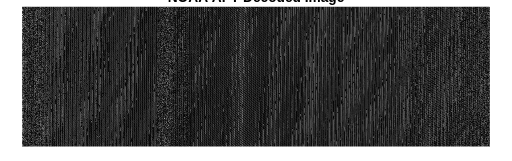

% graph
figure;
imshow(aptImage, []);
colormap gray;
axis equal;
title('NOAA APT Decoded Image');

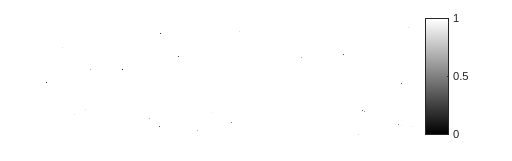


imshow(aptImage);
colormap gray;
colorbar;


imwrite(grayImage, 'grayscale_image.png'); % Save as PNG

Unrecognized function or variable 'grayImage'.